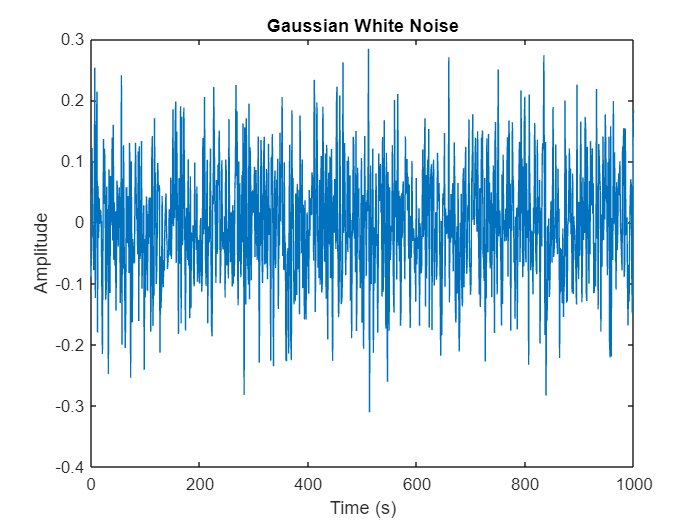

N = 1000;
stdev = 0.1;
noise = init_noise(N, stdev);

Ts = 1;
time = Ts * (0:N-1);

plot(time, noise);

title('Gaussian White Noise');
xlabel('Time (s)');
ylabel('Amplitude');

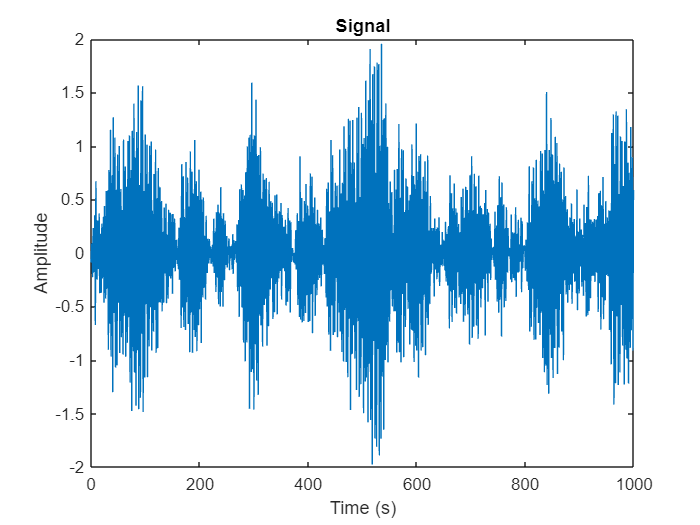

b = 1;
a = [1, 1.4, 0.981];
signal = init_signal(noise, a, b);

plot(time, signal);
title('Signal');
xlabel('Time (s)');
ylabel('Amplitude');

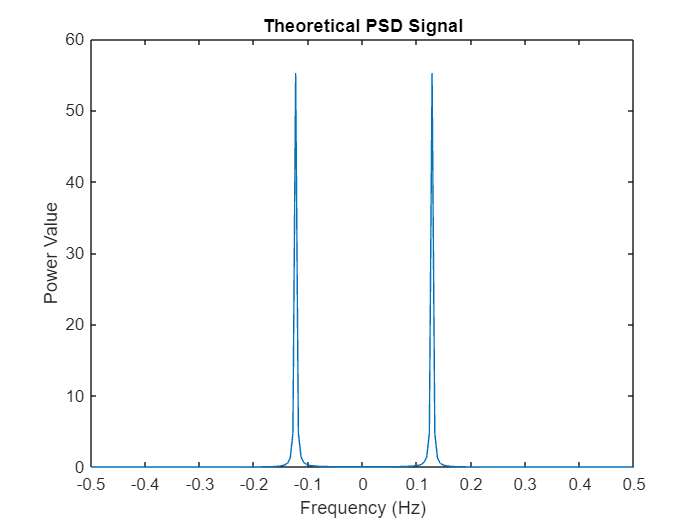

fs = 1/Ts;
N_freqs = 200;

gain = gain_filter(a, b, N_freqs, fs);
psd_signal = gain.^2 * stdev^2;

freqs = linspace(-fs/2, fs/2, N_freqs);
freqs_for_graph = linspace(-fs/2, fs/2, 11);
plot(freqs, psd_signal);
title('Theoretical PSD Signal');
xlabel('Frequency (Hz)');
xticks(freqs_for_graph);
ylabel('Power Value');

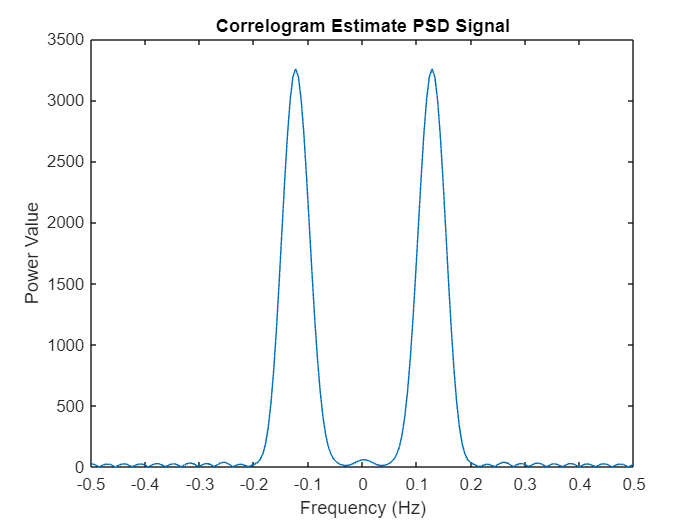

M = 16;
window_correlo = hamming(2*M+1)';

psd_signal_correlo = correlogram(signal, window_correlo, N_freqs);

plot(freqs, psd_signal_correlo);
title('Correlogram Estimate PSD Signal');
xlabel('Frequency (Hz)');
xticks(freqs_for_graph);
ylabel('Power Value');

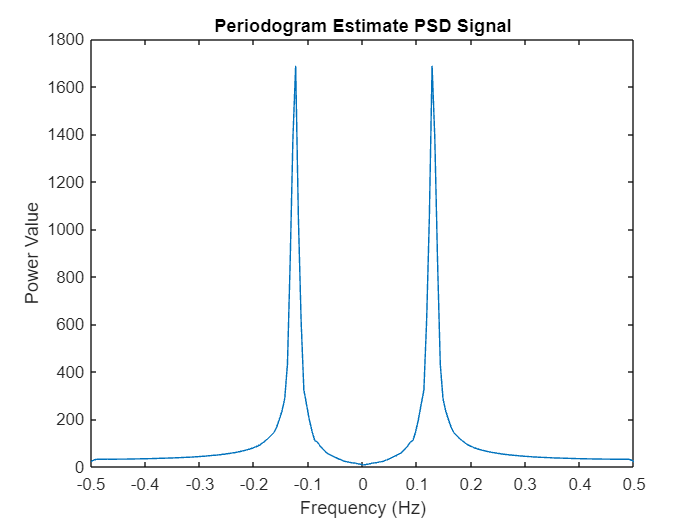

window_periodo = [0.1, 0.2, 0.4, 0.2, 0.1];

psd_signal_periodo = periodogram(signal, window_periodo, N_freqs);

plot(freqs, psd_signal_periodo);
title('Periodogram Estimate PSD Signal');
xlabel('Frequency (Hz)');
xticks(freqs_for_graph);
ylabel('Power Value');

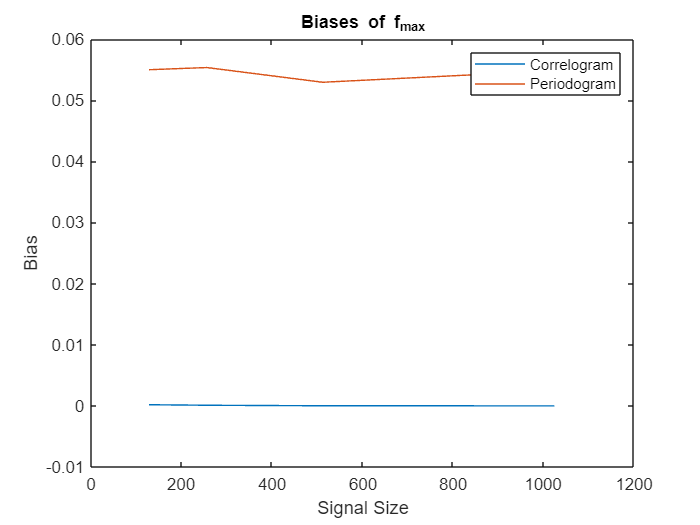

signal_sizes = [128, 256, 512, 1024];
N_reals = 2000;
[~, ind_fmax] = max(psd_signal);
fmax = freqs(ind_fmax);

values_fmax_correlo = zeros(length(signal_sizes), N_reals);
values_fmax_periodo = zeros(length(signal_sizes), N_reals);

for i = 1:length(signal_sizes)

    for real = 1:N_reals
    
        noise = init_noise(signal_sizes(i), stdev);
        signal = init_signal(noise, a, b);
        
        psd_signal_correlo = correlogram(signal, window_correlo, N_freqs);
        [~, ind_fmax_correlo] = max(psd_signal_correlo);
        fmax_correlo = freqs(ind_fmax_correlo);
        values_fmax_correlo(i, real) = fmax_correlo;
    
        psd_signal_periodo = periodogram(signal, window_periodo, N_freqs);
        [~, ind_fmax_periodo] = max(psd_signal_periodo);
        fmax_periodo = freqs(ind_fmax_periodo);
        values_fmax_periodo(i, real) = fmax_periodo;
    end
end

biases_correlo = mean(values_fmax_correlo, 2) - fmax;
biases_periodo = mean(values_fmax_periodo, 2) - fmax;

variances_correlo = var(values_fmax_correlo, 0, 2);
variances_periodo = var(values_fmax_periodo, 0, 2);

plot(signal_sizes, biases_correlo);
hold on;
plot(signal_sizes, biases_periodo);
hold off;
legend("Correlogram", "Periodogram");
title('Biases of f_max');
xlabel('Signal Size');
ylabel('Bias');

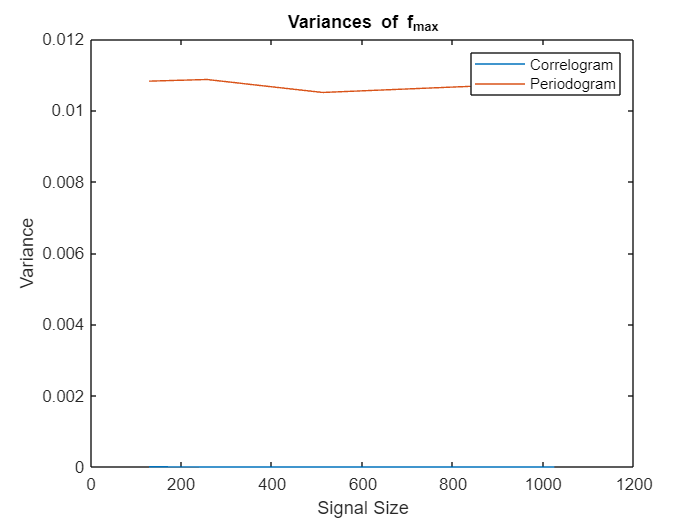

plot(signal_sizes, variances_correlo);
hold on;
plot(signal_sizes, variances_periodo);
hold off;
legend("Correlogram", "Periodogram");
title('Variances of f_max');
xlabel('Signal Size');
ylabel('Variance');

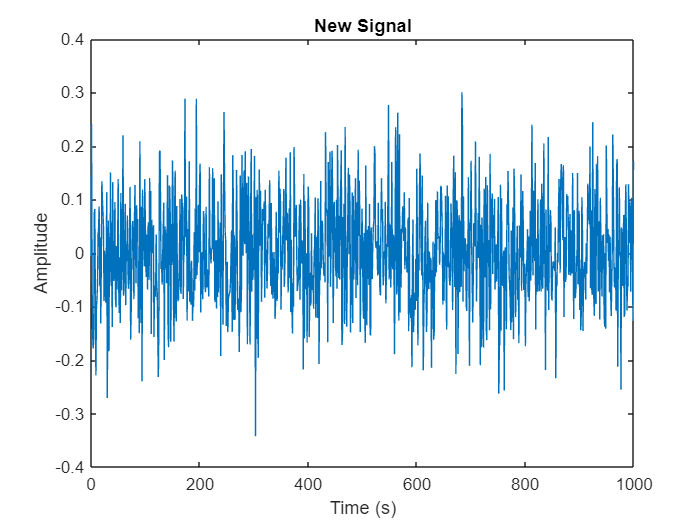

frequencies = [5, 20, 50];
amplitudes = [1, 0.5, 0.2];
sinusoid1 = amplitudes(1) * sin(2*pi*frequencies(1)*time);
sinusoid2 = amplitudes(2) * sin(2*pi*frequencies(2)*time);
sinusoid3 = amplitudes(3) * sin(2*pi*frequencies(3)*time);

new_signal = sinusoid1 + sinusoid2 + sinusoid3 + init_noise(N, stdev);

plot(time, new_signal);
title('New Signal');
xlabel('Time (s)');
ylabel('Amplitude');

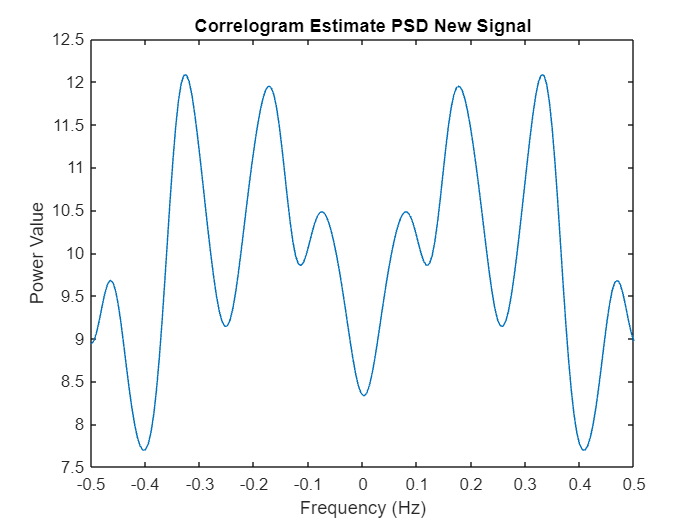

psd_new_signal_correlo = correlogram(new_signal, window_correlo, N_freqs);

plot(freqs, psd_new_signal_correlo);
title('Correlogram Estimate PSD New Signal');
xlabel('Frequency (Hz)');
xticks(freqs_for_graph);
ylabel('Power Value');

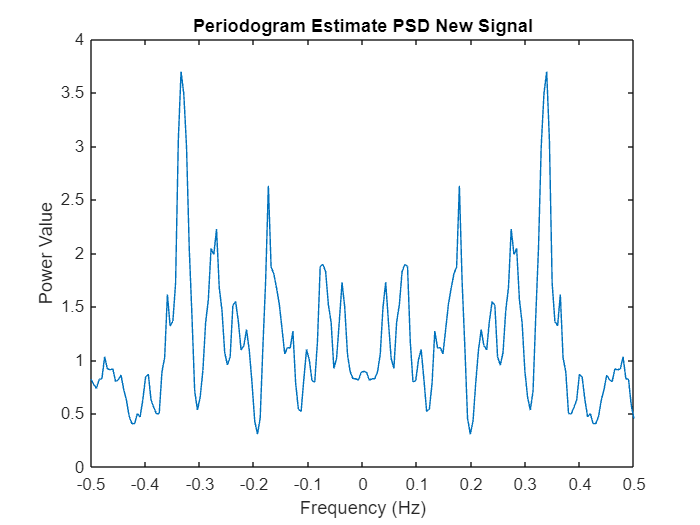

psd_new_signal_periodo = periodogram(new_signal, window_periodo, N_freqs);

plot(freqs, psd_new_signal_periodo);
title('Periodogram Estimate PSD New Signal');
xlabel('Frequency (Hz)');
xticks(freqs_for_graph);
ylabel('Power Value');